I = imread('man.tiff');
I = double(I);
T = dctmtx(8);
dct = @(block_struct) T * block_struct.data * T';
% this would pad image with zeros
B = blockproc(I,[8 8],dct);

upper = 0.7;
lower = 0.15;
[Bq q_ref] = myQ(B, upper, lower);
nnz(Bq)

ans = 110318

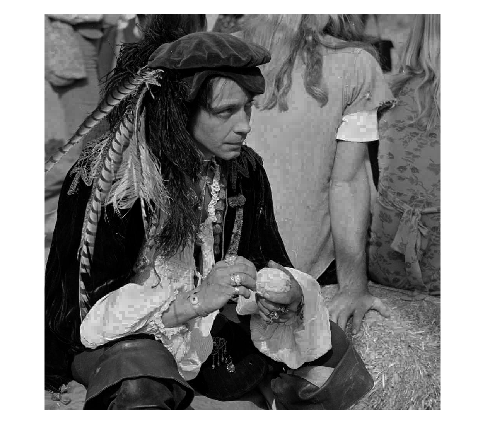

idct = @(block_struct) T' * block_struct.data * T;
Iq = blockproc(Bq,[8 8],idct);
imshow(Iq,[0 255]); truesize;

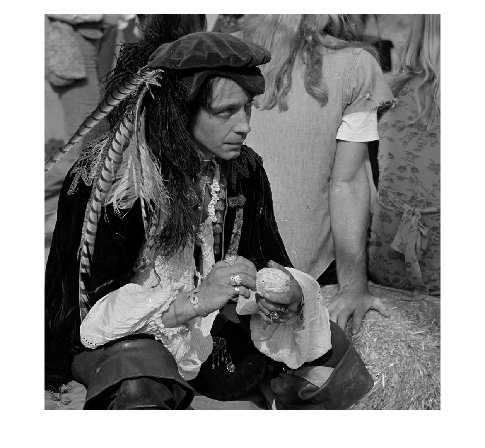

Q_50 = q_factor(50);
aq = blockproc(B,[8 8], @(block_struct) Q_50.* round((block_struct.data) ./ Q_50) );
idct2 = @(block_struct) T' * block_struct.data * T;
Iq2 = blockproc(aq,[8 8],idct2);
imshow(Iq2,[0 255]); truesize;

nnz(aq)

ans = 149435